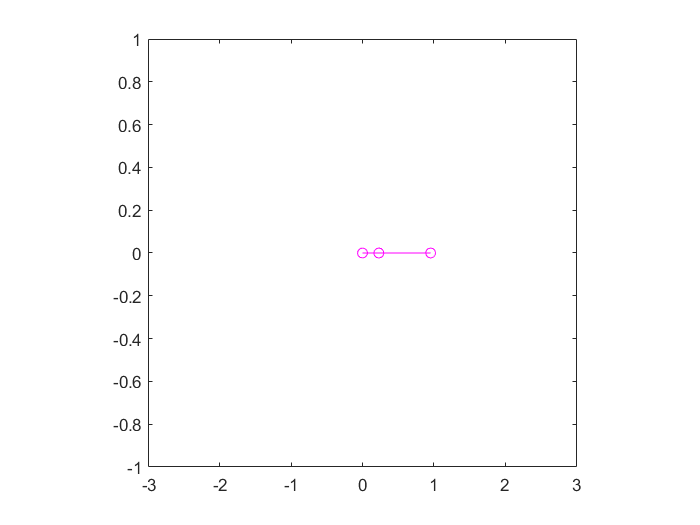

m1=1;
m2=1;

l1=0.5;
l2=1;

k1=2;
k2=2;

x1dot=0;
x2dot=0;

dt=0.1;
ts=10;
t=0:dt:ts;

x1=0.3;
x2=0.7;
% x1dot(length(t))=0;
% x2dot(length(t))=0;

%x1dot(1)=5;

for i=1:length(t)
    x2dotdot=(-k2*(x2(i)-x1(i)))/m2;
    x2dot(i+1)=x2dot(i)+x2dotdot*dt;
    x2(i+1)=x2(i)+x2dot(i+1)*dt;
    
    x1dotdot=(k2*(x2(i)-x1(i))-k1*x1(i))/m1;
    x1dot(i+1)=x1dot(i)+x1dotdot*dt;
    x1(i+1)=x1(i)+x1dot(i+1)*dt;

    
    plot([0 l1+x1(i) l1+l2+x2(i)],[0 0 0],'m-o');
    axis([-3 3 -1 1]);
    axis square;
    pause(dt/10);
end